# 三角波和反三角波比较

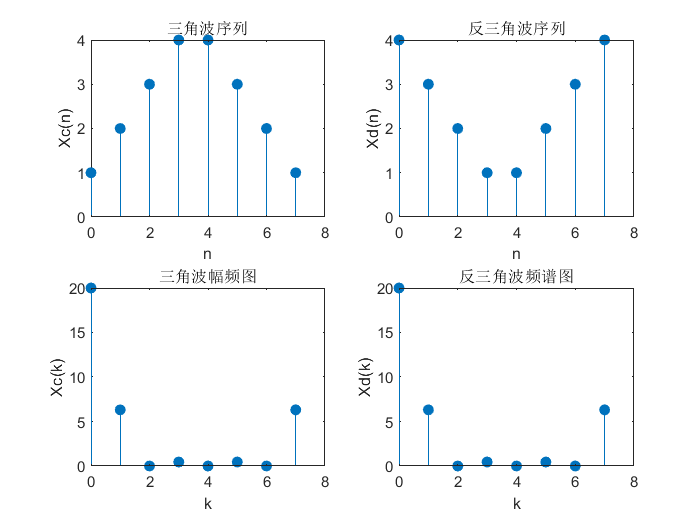

clc
clear 
close all

N = 8;
n = [0:N-1];

%定义三角波序列
i = 0:3;
xc(i+1) = i+1;
i = 4:7;
xc(i+1) = 8-i;
%定义反三角波序列
j = 0:3;
xd(j+1) = 4-j;
j = 4:7;
xd(j+1) = j-3;

%hc为xc的DFT
hc=fft(xc,N);
%hd为xd的DFT
hd=fft(xd,N);

%绘图
subplot(221);
stem(n,xc,'filled');
xlabel('n');
ylabel('Xc(n)');
title('三角波序列');
subplot(222);
stem(n,xd,'filled');
xlabel('n');
ylabel('Xd(n)');
title('反三角波序列');
subplot(223);
stem(n,abs(hc),'filled');
xlabel('k');
ylabel('Xc(k)');
title('三角波幅频图');
subplot(224);
stem(n,abs(hd),'filled');
xlabel('k');
ylabel('Xd(k)');
title('反三角波频谱图');